%%%
% SPDX-License-Identifier: LGPL-3.0-or-later
% Copyright (c) 2025 Zherui Li
%%%

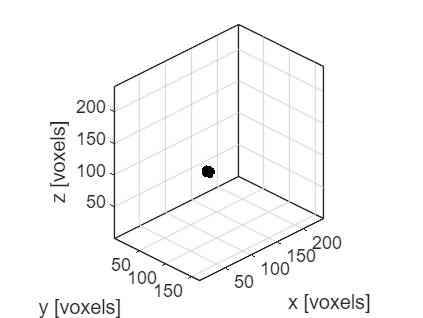

subjectID = 'tFUS0000';

% Read V5 mask
V5_mask = niftiread(['./H-275 3D Simulations/subjects/' subjectID '/' subjectID '_V5_L_native.nii.gz']);
threshold_value = 0;
V5_mask_binary = V5_mask > threshold_value;

% Calculate the scale factor to achieve dx=1.0714 mm
scale_factor = 1 / 1.0714;

% Resample the mask to have the new voxel size
V5_mask_binary = imresize3(V5_mask_binary, scale_factor, 'nearest');

% Rotatation
V5_mask_binary = imrotate3(V5_mask_binary, -90, [0 0 1], 'nearest');

figure
voxelPlot(single(V5_mask_binary));

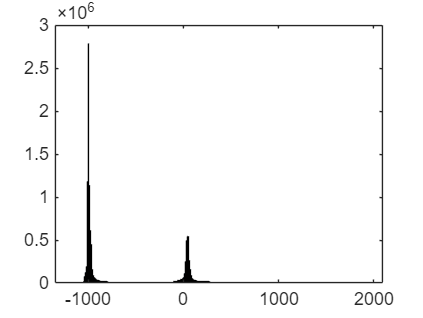

% Load the skull bone image
skull = niftiread(['./H-275 3D Simulations/subjects/' subjectID '/' subjectID '_pct.nii']);

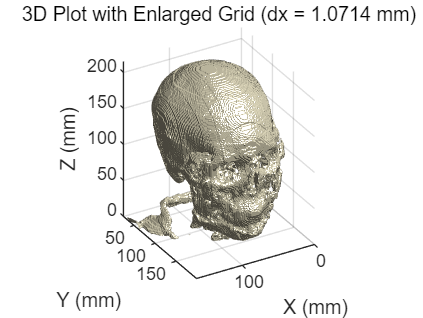


% Create the MNI152 mask
skull_mask = skull;
skull_mask = imresize3(skull_mask, scale_factor, 'nearest');

% Set all elements greater than zero to 1
threshold_value = 140;
skull_mask = skull_mask > threshold_value;

% Rotatation
skull_mask = imrotate3(skull_mask, -90, [0 0 1], 'nearest');

% Get the dimensions of the data
[sz_x, sz_y, sz_z] = size(skull_mask);

% Adjust coordinate vectors to new dx=1.0714 mm
dx_new = 1;  % New voxel size in mm

% Assuming the origin is at 0 mm
x_vec = (0:sz_x-1) * dx_new;  % New x coordinates
y_vec = (0:sz_y-1) * dx_new;  % New y coordinates
z_vec = (0:sz_z-1) * dx_new;  % New z coordinates

% Generate the grids using the new coordinate vectors
[X, Y, Z] = meshgrid(y_vec, x_vec, z_vec);

figure;
% Plot the skull mask
p2 = patch(isosurface(X, Y, Z, skull_mask, 0.5));  % Using 0.5 threshold to capture the skull boundary
isonormals(X, Y, Z, skull_mask, p2);
set(p2, 'FaceColor', [0.95, 0.92, 0.8], 'EdgeColor', 'none', 'FaceAlpha', 1);  % Set transparency to 30% for the skull
% Plot the brain mask
p3 = patch(isosurface(X, Y, Z, V5_mask_binary, 0.5));  % Using 0.5 threshold to capture the brain region boundary
isonormals(X, Y, Z, V5_mask_binary, p3);
set(p3, 'FaceColor', 'red', 'EdgeColor', 'none', 'FaceAlpha', 1);  % Set transparency to 30% for the brain

% Set viewing parameters
xlabel('X (mm)');
ylabel('Y (mm)');
zlabel('Z (mm)');
title('3D Plot with Enlarged Grid (dx = 1.0714 mm)');
axis tight;
daspect([1 1 1]);
view(180-30,30);
camlight;
lighting gouraud;
grid on;
hold off;

% Load transducer model
transducerModel = stlread('./example/transducers/H275Transducer/Digital Model/FakeTransducer_V4.STL');

% Use the triangulation object's properties
vertices = transducerModel.Points;
faces = transducerModel.ConnectivityList;

% Get the bounding box (size) of the model to check if units is correct
minCoords = min(vertices);
maxCoords = max(vertices);
modelSize = maxCoords - minCoords;
disp(modelSize);

   85.2400   85.2076   70.0000



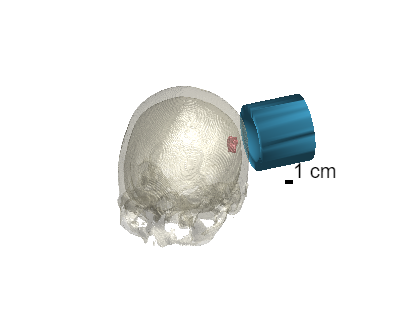


% Define a 90° rotation about the x/y/z axis
theta = deg2rad(-90);  % Convert 90 degrees to radians
% R_x = [1, 0, 0; 
%        0, cos(theta), -sin(theta); 
%        0, sin(theta), cos(theta)];
R_y = [cos(theta), 0, sin(theta);
       0, 1, 0;
       -sin(theta), 0, cos(theta)];
% Then, 45° rotation
theta = deg2rad(45);
R_z = [cos(theta), -sin(theta), 0;
       sin(theta), cos(theta), 0;
       0, 0, 1];

% Apply the rotation to the vertices
rotatedVertices = (R_y * vertices')';
rotatedVertices = (R_z * rotatedVertices')';

% Define the translation vector
translationVector = [60, 5, 39];

% Translate the vertices by adding the translation vector to each vertex
translatedVertices = rotatedVertices + translationVector;

figure
% Plot the skull mask
p1 = patch(isosurface(X, Y, Z, skull_mask, 0.5));  % Using 0.5 threshold to capture the skull boundary
isonormals(X, Y, Z, skull_mask, p1);
set(p1, 'FaceColor', [0.95, 0.92, 0.8], 'EdgeColor', 'none', 'FaceAlpha', 0.3);  % Set transparency to 30% for the skull
hold on

% Plot the brain mask
p2 = patch(isosurface(X, Y, Z, V5_mask_binary, 0.5));  % Using 0.5 threshold to capture the brain region boundary
isonormals(X, Y, Z, V5_mask_binary, p2);
set(p2, 'FaceColor', [0.6350 0.0780 0.1840], 'EdgeColor', 'none', 'FaceAlpha', 1);  % Set transparency to 30% for the brain
hold on

% Plot the transducer model
p3 = patch('Vertices', translatedVertices, 'Faces', faces, ...
           'FaceColor', [0.3010 0.7450 0.9330], 'EdgeColor', 'none', 'FaceAlpha', 1);
% Compute vertex normals using the triangulation object
tn = triangulation(faces, translatedVertices);
set(p3, 'VertexNormals', tn.vertexNormal);
hold on

% Set viewing parameters
axis tight;
daspect([1 1 1]);
view(-155,35);
camlight;
lighting gouraud;
axis off

% Draw a 10 mm ref line
ax = gca; % Get the current axes handle
% Retrieve camera properties
camPos = get(ax, 'CameraPosition');
camTgt = get(ax, 'CameraTarget');
camUp  = get(ax, 'CameraUpVector');
% Compute the camera view direction (from camera to target)
camDir = camTgt - camPos;
camDir = camDir / norm(camDir);
% The right vector is perpendicular to camDir and the camera up vector
rightVec = cross(camDir, camUp);
rightVec = rightVec / norm(rightVec);
% Choose a reference point
refPoint = [0, 0, 0];
% Compute the endpoint for a 10 mm line in the rightVec direction
endPoint = refPoint + 10 * rightVec;
% Plot the 10 mm reference line
plot3([refPoint(1) endPoint(1)], [refPoint(2) endPoint(2)], [refPoint(3) endPoint(3)], 'k', 'LineWidth', 2);
% Add a text label at the end of the line
text(endPoint(1), endPoint(2), endPoint(3), '1 cm', 'Color', 'k', 'FontSize', 10, ...
     'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');
hold off;